syms il L r ra b c kf w km kw h J vin s 

ilp=(1/L)*(vin-ra*il-kw*w)

$$ilp = -\frac{\mathrm{il}\,\mathrm{ra}-\mathrm{vin}+\mathrm{kw}\,w}{L}$$

wp=(1/J)*(km*il-b*w)

$$wp = \frac{\mathrm{il}\,\mathrm{km}-b\,w}{J}$$

hp=(1/c)*(kf*w-h*r)

$$hp = -\frac{h\,r-\mathrm{kf}\,w}{c}$$

xe=[il,w,h]

$$xe = \left(\begin{array}{ccc} \mathrm{il} & w & h \end{array}\right)$$

y=h

$$y = h$$


A=jacobian([ilp,wp,hp],xe)

$$A = \left(\begin{array}{ccc} -\frac{\mathrm{ra}}{L} & -\frac{\mathrm{kw}}{L} & 0\\ \frac{\mathrm{km}}{J} & -\frac{b}{J} & 0\\ 0 & \frac{\mathrm{kf}}{c} & -\frac{r}{c} \end{array}\right)$$

B=jacobian([ilp,wp,hp],vin)

$$B = \left(\begin{array}{c} \frac{1}{L}\\ 0\\ 0 \end{array}\right)$$

C=jacobian(y,xe)

$$C = \left(\begin{array}{ccc} 0 & 0 & 1 \end{array}\right)$$

D=jacobian(y,vin)

$$D = 0$$


Fs=C*(inv(eye(3)*s-A))*B+D

$$Fs = \frac{\mathrm{kf}\,\mathrm{km}}{b\,r\,\mathrm{ra}+\mathrm{km}\,\mathrm{kw}\,r+J\,r\,\mathrm{ra}\,s+b\,c\,\mathrm{ra}\,s+c\,\mathrm{km}\,\mathrm{kw}\,s+J\,L\,c\,s^{3}+J\,L\,r\,s^{2}+L\,b\,c\,s^{2}+J\,c\,\mathrm{ra}\,s^{2}+L\,b\,r\,s}$$


ra=1

ra = 1

r=1

r = 1

L=1

L = 1

J=1

J = 1

c=1

c = 1

km=1

km = 1

kw=1

kw = 1

kf=0.5

kf = 0.5000

b=1

b = 1

L=1

L = 1


A=double(eval(A))

A =    -1.0000   -1.0000         0
    1.0000   -1.0000         0
         0    0.5000   -1.0000


B=double(eval(B))

B =      1
     0
     0


C=double(eval(C))

C =      0     0     1


D=double(eval(D))

D = 0


Fss=C*(inv(eye(3)*s-A))*B+D

$$Fss = \frac{1}{2\,\left(s^{3}+3\,s^{2}+4\,s+2\right)}$$

[num,den]=ss2tf(A,B,C,D)

num =          0         0         0    0.5000


den =      1     3     4     2


ft=tf(num,den)

ft =
 
           0.5
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.



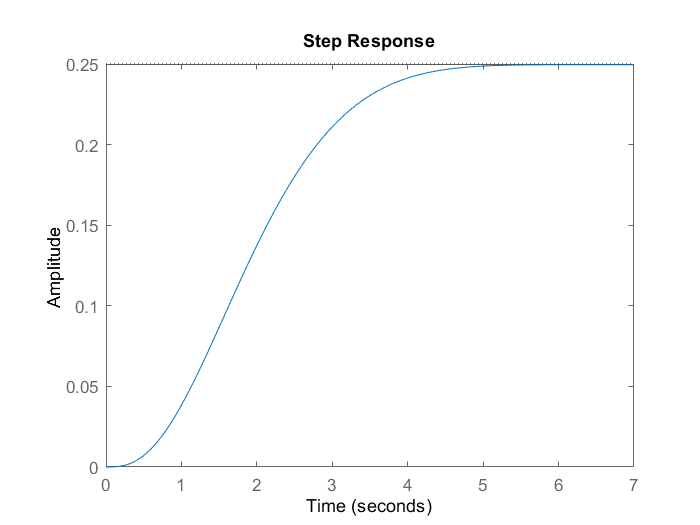

step(ft)

ts=4

ts = 4

zeta=0.8

zeta = 0.8000

wn=4/(zeta*ts)

wn = 1.2500

pd=[1 2*zeta*wn wn^2]

pd =     1.0000    2.0000    1.5625


polND=[1 10*zeta*wn]

polND =      1    10


pd=conv(pd,polND)%orden3

pd =     1.0000   12.0000   21.5625   15.6250


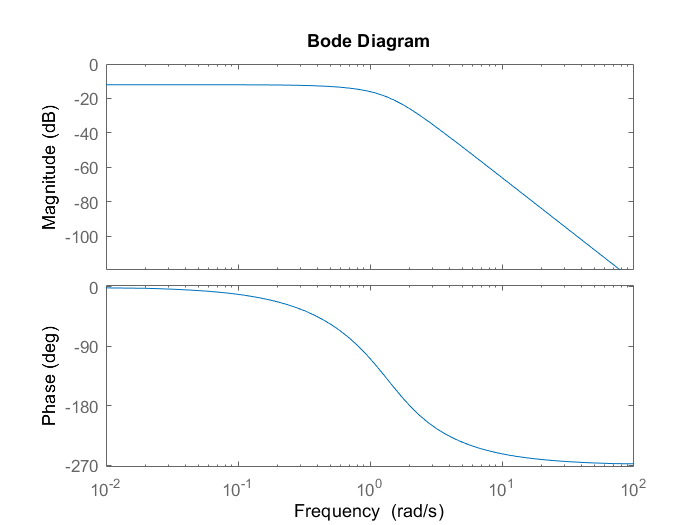

bode(ft)

%%%%
Ftdisc=c2d(ft,0.866/20,'tustin')

Ftdisc =
 
  4.756e-06 z^3 + 1.427e-05 z^2 + 1.427e-05 z + 4.756e-06
  -------------------------------------------------------
            z^3 - 2.871 z^2 + 2.749 z - 0.8782
 
Sample time: 0.0433 seconds
Discrete-time transfer function.



%syms ki ki2 kp kd kd2 
kd2=50.88888

kd2 = 50.8889

kd1=563.358025

kd1 = 563.3580

kp=2309.3059

kp = 2.3093e+03

ki1=3082.45694

ki1 = 3.0825e+03

ki2=1734.152999

ki2 = 1.7342e+03

numPid=[kd2,kd1,kp,ki1,ki2]

numPid = 	1.0e+03 *

    0.0509    0.5634    2.3093    3.0825    1.7342


FtPID=tf(numPid,[0 0 1 0 0])

FtPID =
 
  50.89 s^4 + 563.4 s^3 + 2309 s^2 + 3082 s + 1734
  ------------------------------------------------
                        s^2
 
Continuous-time transfer function.



FtPIDdisc=c2d(FtPID,0.866/20,'tustin')

FtPIDdisc =
 
  1.37e05 z^4 - 4.862e05 z^3 + 6.468e05 z^2 - 3.824e05 z + 8.479e04
  -----------------------------------------------------------------
                           z^4 - 2 z^2 + 1
 
Sample time: 0.0433 seconds
Discrete-time transfer function.

